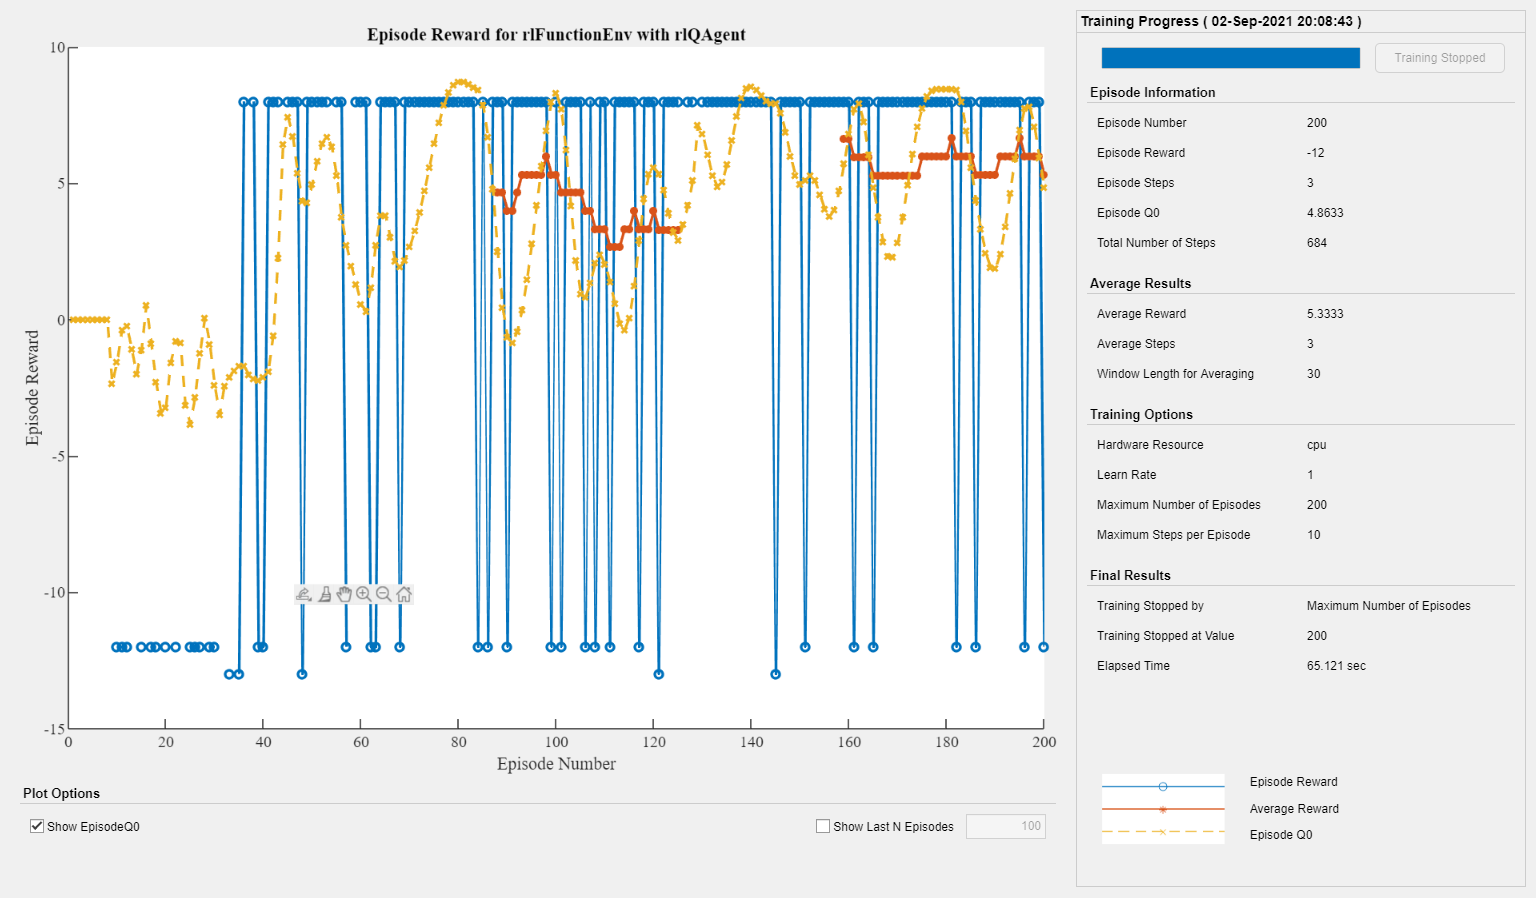

%	Initialise script
Proj = currentProject;
cd(fullfile(Proj.RootFolder, "TicTacToe"));

% %	Create TicTacToe object
% TTT = TicTacToe;

%	Create environment
NumObs = 3^9;		%	Number of observation states (Pl 1, Pl 2 or empty in each grid position)
NumAct = 9;			%	Number of actions (3x3 grid)

OI = rlFiniteSetSpec(1:NumObs);		%	Observation Info
OI.Name = "Tic-Tac-Toe Observation States";

AI = rlFiniteSetSpec(1:NumAct);		%	Action Info
OI.Name = "Tic-Tac-Toe Actions";

env = rlFunctionEnv(OI, AI, @Step, @Reset);
%	Create QTable
qTable = rlTable(OI, AI);
qRepresentation = rlQValueRepresentation(qTable, OI, AI);
qRepresentation.Options.LearnRate = 1;

%	Create Agent Options
agentOpts = rlQAgentOptions;
agentOpts.EpsilonGreedyExploration.Epsilon = .04;
agentOpts.EpsilonGreedyExploration.EpsilonMin = 1e-3;
qAgent = rlQAgent(qRepresentation, agentOpts);

%	Set training options
trainOpts = rlTrainingOptions;
trainOpts.MaxStepsPerEpisode = 10;
trainOpts.MaxEpisodes= 200;
trainOpts.StopTrainingCriteria = "AverageReward";
trainOpts.StopTrainingValue = 41;
trainOpts.ScoreAveragingWindowLength = 30;

%	Train the agent
rng(0);
trainingStats = train(qAgent, env, trainOpts);

function [InitObs, TTT] = Reset()
	InitObs = 1;
	TTT = TicTacToe;
end

%	Step by applying the action to the game board
function [Obs, Reward, IsDone, TTT] = Step(Action, TTT)
Rewards = struct( ...
	"Step", -1, ...
	"Win", 10, ...
	"Draw", 5, ...
	"Lose", -10, ...
	"Illegal", -inf);

%	Store current player to check for illegal moves
CurrentPlayer = TTT.CurrentPlayer;

%	Attempt to insert counter in grid index Action
[Row, Col] = ind2sub([3 3], Action);
TTT = TTT.Insert(Row, Col);

%	If currentplayer not changed, then return illegal move
if CurrentPlayer == TTT.CurrentPlayer
	Result = nan;
else
	Result = TTT.CheckWinner;
	if abs(Result)~=1
		TTT = TTT.Choose;
		Result = TTT.CheckWinner;
	end
end

switch Result
	case 1
		Reward = Rewards.Win;
	case 2
		Reward = Rewards.Lose;
	case -1
		Reward = Rewards.Draw;
	case 0
		Reward = Rewards.Step;
	otherwise
		Reward = Rewards.Illegal;
end
if isfinite(Result) && logical(Result)
	IsDone = true;
else
	IsDone = false;
end

Obs = sum(3.^(0:8).' .* mod(TTT.Grid(:), 3)) + 1;
end
